clear;clc;close all
load UCIDB.mat

% normalization
% z-score


FS =   trainFuzzSys with properties:

    X_train: [270×13 double]
    y_train: [270×1 double]
     n_data: 270
      n_dim: 13
    sysType: []
    Results: []


Percent explained by 2 first component : 89.55 %

n_feature = 2

FS =   trainFuzzSys with properties:

    X_train: [270×2 double]
    y_train: [270×1 double]
     n_data: 270
      n_dim: 2
    sysType: []
    Results: []


n_clus = 99

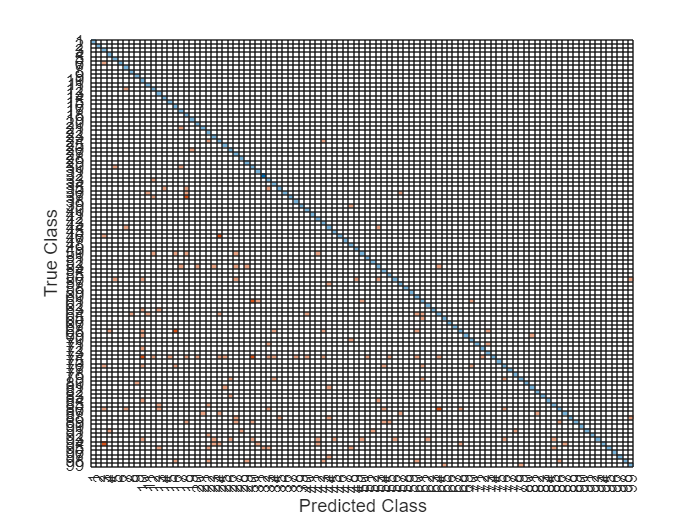

clustering_measure_clus1 = struct with fields:
     Accuracy: 0.3704
    Precision: 1
       Recall: 1
      F1Score: 1


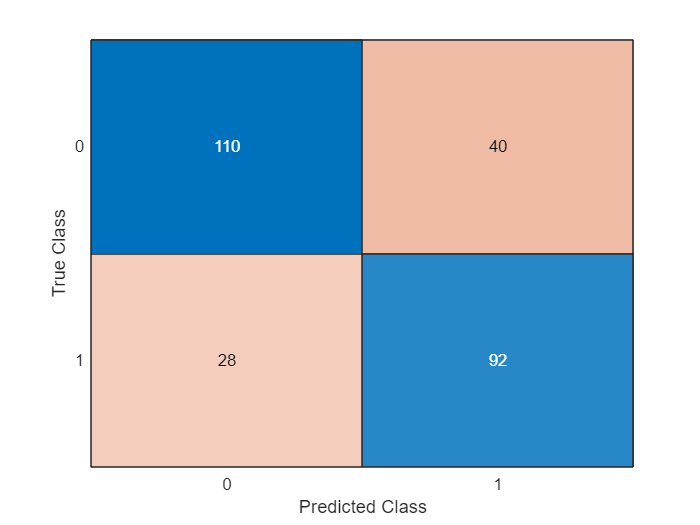

regWithThreshold_measure_clus1 = struct with fields:
     Accuracy: 0.7481
    Precision: 0.7971
       Recall: 0.7333
      F1Score: 0.7639


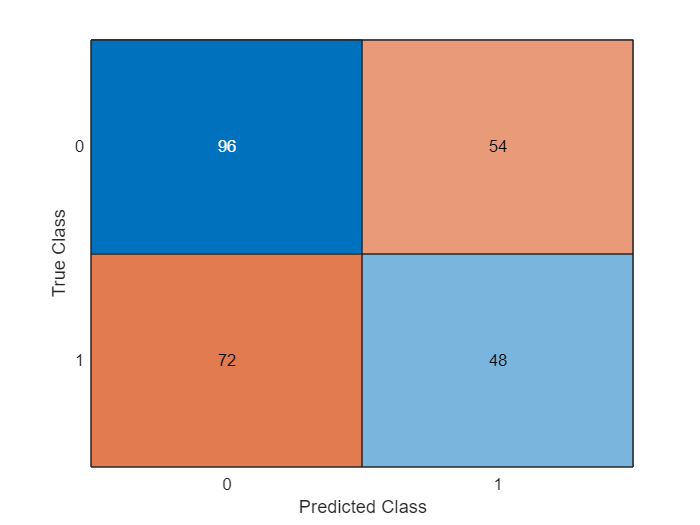

regWithThreshold_measure_clus2 = struct with fields:
     Accuracy: 0.5333
    Precision: 0.5714
       Recall: 0.6400
      F1Score: 0.6038


r = 9;
sigma = 2;
k = 2;
project(data,labels,r,sigma,k)

# **functions**

function project(data,labels,r,sigma,k)
    if nargin == 5
        data = dataReduction(data,k);
    end
    n_feature = size(data,2)
    FS = trainFuzzSys(data,labels)
    clus1 = FS.Clustering(r);
    n_clus = clus1.Results.n_clus
    results = clus1.test(data,sigma);
    clustering_measure_clus1 = evaluateClassification(clus1.Results.dataCluster, results.clustering)
    estimateFromRegression = double(results.regression >= 0.5);
    regWithThreshold_measure_clus1 = evaluateClassification(labels, estimateFromRegression)

    clus2 = FS.Clustering2(r,'gauss',sigma);
    est = clus2.test(data);
    est = double(est >= 0.5);
    regWithThreshold_measure_clus2 = evaluateClassification(labels, est')
end

%%

function DataReduced = dataReduction(data,k)
    % Determine the number of components to reduce dimensions
    % For example, reduce to 1 components
    % Calculate the average of each column and center the data
    DataMean = mean(data);
    DataCentered = data - DataMean;
    % Perform PCA
    [~,score,~,~,explained] = pca(DataCentered);
    % use of k principal components
    DataReduced = score(:,1:k);
    % Displays the percentage explained by the first k components
    explainedVariance = sum(explained(1 : k));
    fprintf('Percent explained by %d first component : %.2f %%',k,explainedVariance);
end

%%

function metrics = evaluateClassification(trueLabels, predictedLabels)
    % Create a confusion matrix
    cm = confusionmat(trueLabels, predictedLabels);
    
    % Calculate metrics
    accuracy = sum(diag(cm)) / sum(cm(:));
    precision = cm(1,1) / sum(cm(:,1));
    recall = cm(1,1) / sum(cm(1,:));
    f1Score = 2 * (precision * recall) / (precision + recall);
    
    % Create a confusion matrix plot
    figure;
    confusionchart(trueLabels, predictedLabels);
    
    % Store metrics in a structure
    metrics = struct('Accuracy', accuracy, ...
        'Precision', precision, 'Recall', recall, 'F1Score', f1Score);
end